- Plot the distribution

- Execute the testing

bins = 0:186;
titles = ["Correlation", "Correlation with trace compression", "Euclidean distance", "Euclidean distance with trace compression"];
format short
psame = 0.1360;
indexesCharacterization = [1 5 6 10];

%Load data
load('./attack_results/v7_first_op.mat')
load('./results_characterization/v7_first_op.mat')

%Separate between collision and not collision
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

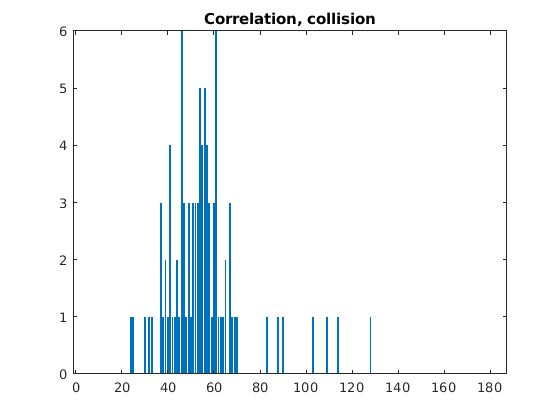

Parameters:


Mean= 55.2903


Variance = 291.0778


estP = 0.2973

Compared to characterization: 


Mean= 150.4317


Variance= 28.7667


P= 0.80877


Chi-squared test for estimated P:


%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Not collision distributions

for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = psame * selectedPoints(indexesCharacterization(i),7) + (1 - psame) * selectedPoints(indexesCharacterization(i),6);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Load data
load('./attack_results/v7_second_op.mat')
load('./results_characterization/v7_second_op_3.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Not collision distributions

for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = psame * selectedPoints(indexesCharacterization(i),7) + (1 - psame) * selectedPoints(indexesCharacterization(i),6);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Load data
load('./attack_results/v9_first_op.mat')
load('./results_characterization/v9_first_op.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Not collision distributions

for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = psame * selectedPoints(indexesCharacterization(i),7) + (1 - psame) * selectedPoints(indexesCharacterization(i),6);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Load data
load('./attack_results/v9_second_op.mat')
load('./results_characterization/v9_second_op.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

%Not collision distributions

for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = psame * selectedPoints(indexesCharacterization(i),7) + (1 - psame) * selectedPoints(indexesCharacterization(i),6);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP)
    disp("Chi-squared test for estimated P:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,estP,"yes")
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test for P from characterization:");
    [htest,chi2stat,pvaluetest,df] = chi2testbinomial(counts,charP,"no")
end

**Recommendation: Get more data**, chi-squared test is not suitable. Fischer test could be used.